## Assigment-Q3, Q4

#### Q3

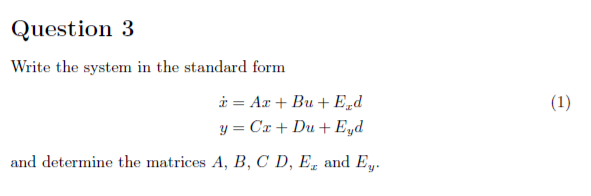

clear all;
close all;
clc;
%%Parameters:

syms J_1 J_2 J_3 k_1 k_2 b_1 b_2 b_3
input_switch=0;
%% State space representation
A = [0 1 0 0 0 0;
    -k_1/J_1 -b_1/J_1 k_1/J_1 0 0 0;
    0 0 0 1  0 0;
    k_1/J_2 0 (-k_1-k_2)/J_2 -b_2/J_2 k_2/J_2 0;
    0 0 0 0 0 1;
    0 0 k_2/J_3 0 -k_2/J_3 -b_3/J_3];
B = [0 1/J_1 0 0 0 0]';
C = [ 1 0 0 0 0 0;
      0 0 1 0 0 0;
      0 0 0 0 1 0];
D = 0;

E_x = [0 -1/J_1 0 0 0 0]';
E_y = [0 0 0]';


Conclusion:

-As the provided system is already linearised, from the equations, is possible to obtain all the matrices.

#### Q4

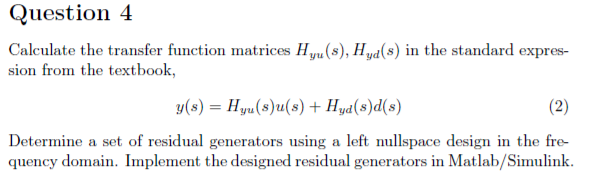

syms s

%Hyu and Hyd

Hyu=C*inv(s*eye(size(A,1))-A)*B+D;
Hyd=C*inv(s*eye(size(A,1))-A)*E_x+E_y;

%H matrix

I=eye(size(Hyu,2));
H=[Hyu Hyd;I  zeros(size(Hyu,2),size(Hyd,2))];

%H_sim: simplified H

com_den=gcd(H); %greatest common divisor
H_sim=simplify(H./com_den);

%rank H_sim

rank_H_sim=rank(H_sim)

rank_H_sim = 2


%F matrix: left nullspace matrix

F=null(H_sim')'

$$F = \begin{array}{l} \left(\begin{array}{cccc} -\frac{k_{1}\,\left(J_{3}\,s^{2}+b_{3}\,s+k_{2}\right)}{\sigma_{1}} & 1 & 0 & 0\\ -\frac{k_{1}\,k_{2}}{\sigma_{1}} & 0 & 1 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=k_{1}\,k_{2}+b_{2}\,k_{2}\,s+b_{3}\,k_{1}\,s+b_{3}\,k_{2}\,s+J_{2}\,J_{3}\,s^{4}+J_{2}\,b_{3}\,s^{3}+J_{3}\,b_{2}\,s^{3}+J_{2}\,k_{2}\,s^{2}+J_{3}\,k_{1}\,s^{2}+J_{3}\,k_{2}\,s^{2}+b_{2}\,b_{3}\,s^{2} \end{array}$$


%Vry and Vru:

Vry=F(:,1:3)

$$Vry = \begin{array}{l} \left(\begin{array}{ccc} -\frac{k_{1}\,\left(J_{3}\,s^{2}+b_{3}\,s+k_{2}\right)}{\sigma_{1}} & 1 & 0\\ -\frac{k_{1}\,k_{2}}{\sigma_{1}} & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=k_{1}\,k_{2}+b_{2}\,k_{2}\,s+b_{3}\,k_{1}\,s+b_{3}\,k_{2}\,s+J_{2}\,J_{3}\,s^{4}+J_{2}\,b_{3}\,s^{3}+J_{3}\,b_{2}\,s^{3}+J_{2}\,k_{2}\,s^{2}+J_{3}\,k_{1}\,s^{2}+J_{3}\,k_{2}\,s^{2}+b_{2}\,b_{3}\,s^{2} \end{array}$$

Vru=F(:,4);

%Residual generators, leftnullspace design, frequency domain:

syms y y1 y2 y3 u
y=[y1;y2;y3];

r=Vry*y+Vru*u

$$r = \begin{array}{l} \left(\begin{array}{c} y_{2}-\frac{k_{1}\,y_{1}\,\left(J_{3}\,s^{2}+b_{3}\,s+k_{2}\right)}{\sigma_{1}}\\ y_{3}-\frac{k_{1}\,k_{2}\,y_{1}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=k_{1}\,k_{2}+b_{2}\,k_{2}\,s+b_{3}\,k_{1}\,s+b_{3}\,k_{2}\,s+J_{2}\,J_{3}\,s^{4}+J_{2}\,b_{3}\,s^{3}+J_{3}\,b_{2}\,s^{3}+J_{2}\,k_{2}\,s^{2}+J_{3}\,k_{1}\,s^{2}+J_{3}\,k_{2}\,s^{2}+b_{2}\,b_{3}\,s^{2} \end{array}$$


%Verify design:

verify=simplify(Vry*Hyd)

$$verify = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$


%Parameters for simulation

T_s = 0.004;                          % Sampling period
sigma_meas = deg2rad(0.0056)*[1;1;1]; % Measurements noise
f_m = [0;-0.125;0];                   % Sensor fault vector (added to [y1;y2;y3])

% The system states are [theta_1;omega_1;theta_2;omega_2;theta_3;omega_3]
x_0 = [0;0;0;0;0;0];                  % Initial conditions

simTime = 700;                        % Simulation duration in seconds
f_m_time = 300;                       % Sensor fault occurence time

%plots based on the simulation

load('ECP_values.mat');


% Physical system parameters
J_1 = 0.0025;                   % Disk 1 inertia kgm^2
J_2 = 0.0018;                   % Disk 2 inertia kgm^2
J_3 = 0.0018;                   % Disk 3 inertia kgm^2
k_1 = 2.7;                      % Shaft 1-2 stiffness Nm/rad
k_2 = 2.6;                      % Shaft 2-3 stiffness Nm/rad
b_1 = 0.0029;                   % Disk 1 damping and friction Nms/rad
b_2 = 0.0002;                   % Disk 2 damping and friction Nms/rad
b_3 = 0.00015;                  % Disk 3 damping and friction Nms/rad
T_Cp = ECP_values(12);          % Disk 1 Coulomb friction in positive direction
T_Cm = ECP_values(13);          % Disk 1 Coulomb friction in negative direction
atan_scale = 100;               % Sign approximation factor
w_th = 0.75;                    % Threshold angular velocity rad/s

%Evaluate Vry and Vru:

Vru = eval(Vru);
Vry = eval(Vry);

%Convert Vru and Vry to tf:

[num_11,den_11] = numden(Vry(1,1));
[num_21,den_21] = numden(Vry(2,1));

num_tf_11 = sym2poly(num_11);       %Transform num to polynomial
den_tf_11= sym2poly(den_11);        %Transform den to polynomial
G_Vry_11 =tf(num_tf_11,den_tf_11)   %Transfer fnc Vry(1,1)


G_Vry_11 =
 
               -2.295e24 s^2 - 1.913e23 s - 3.315e27
  ----------------------------------------------------------------
  1.53e21 s^4 + 2.975e20 s^3 + 6.715e24 s^2 + 6.21e23 s + 3.315e27
 
Continuous-time transfer function.




num_tf_21 = sym2poly(num_21);       %Transform num to polynomial
den_tf_21= sym2poly(den_21);        %Transform den to polynomial
G_Vry_21 =tf(num_tf_21,den_tf_21)   %Transfer fnc Vry(1,1)


G_Vry_21 =
 
                             -3.315e27
  ----------------------------------------------------------------
  1.53e21 s^4 + 2.975e20 s^3 + 6.715e24 s^2 + 6.21e23 s + 3.315e27
 
Continuous-time transfer function.




%Vry and Vru as transfer fnc:

Vry=[G_Vry_11 1 0;G_Vry_21 0 1]


Vry =
 
  From input 1 to output...
                    -2.295e24 s^2 - 1.913e23 s - 3.315e27
   1:  ----------------------------------------------------------------
       1.53e21 s^4 + 2.975e20 s^3 + 6.715e24 s^2 + 6.21e23 s + 3.315e27
 
                                  -3.315e27
   2:  ----------------------------------------------------------------
       1.53e21 s^4 + 2.975e20 s^3 + 6.715e24 s^2 + 6.21e23 s + 3.315e27
 
  From input 2 to output...
   1:  1
 
   2:  0
 
  From input 3 to output...
   1:  0
 
   2:  1
 
Continuous-time transfer function.



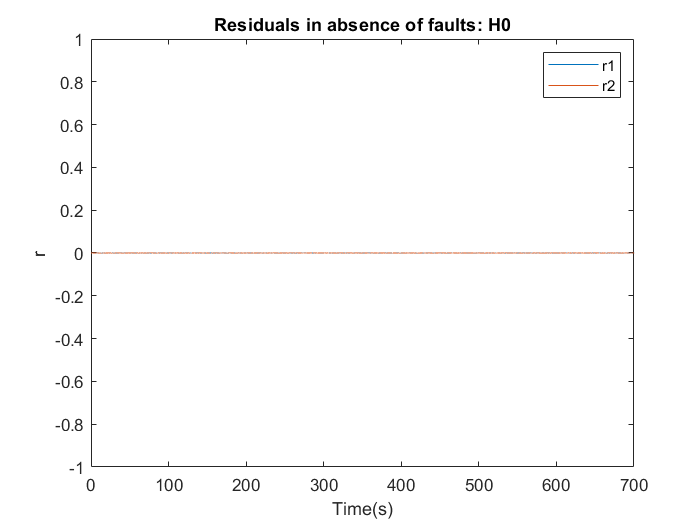


%Filter parameters for the residuals:
wn=1;                           %natural frequency
zeta=0.96;                      %damping

%H0: residual plot
load('test1.mat','u')
input_switch=0;
switch_fault=0;
sim('Q4_Simulink');

figure
plot(r.time,r.signals.values(:,1),r.time,r.signals.values(:,2))
title('Residuals in absence of faults: H0')
ylabel('r')
xlabel('Time(s)')
legend('r1','r2')
ylim([-1 1])

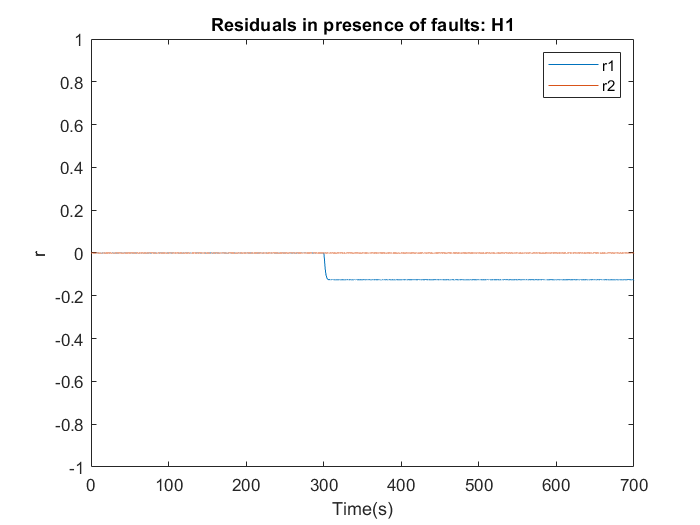


%H1: residual plot

switch_fault=1;
sim('Q4_Simulink');

figure
plot(r.time,r.signals.values(:,1),r.time,r.signals.values(:,2))
title('Residuals in presence of faults: H1')
ylabel('r')
xlabel('Time(s)')
legend('r1','r2')
ylim([-1 1])

input_switch=1;
simTime=17;
f_m_time=8.5;
sim('Q4_Simulink.slx')
fig4=figure

fig4 =   Figure (4) with properties:

      Number: 4
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [488 342 560 420]
       Units: 'pixels'

  Show all properties


yyaxis left
plot(u1.time,u1.signals.values,'LineWidth',1.5)
ylabel('u(t)')
hold on
yyaxis right
plot(r.time,r.signals.values(:,1),'LineWidth',1.5)
hold on
plot(r.time,r.signals.values(:,2),'k-','LineWidth',1.5)
title('System output and residuals')
ylabel('Residuals')
xlabel('Time(s)')
legend('u','r_1','r_2','Interpeter','Latex','Location','northwest')

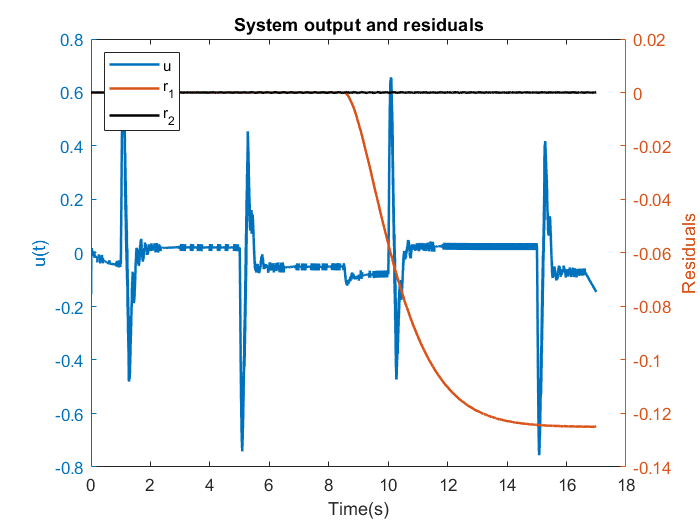

saveas(fig4,'simulation4.png')

Conclusion:

-From the linearised system, is possible to obtain Hyu, Hyd.

-Leftnullspace of matrix H, composed by Hyu and Hyd, defines  matrix F.

-The residual generator is obtained from the leftnullspace matrix.

-Vry*Hyd=0, verifies that the residual generator is made from the leftnullspace.